population/gdp data

clf
% lcc_pop_gdp_country = readtable('../stats/lcc_pop_gdp_country.csv','ReadRowNames',true);
lcc_pop_gdp_country = readtable('../stats/lcc_table_full.csv','ReadRowNames',true);

nodes number vs population colored by GDP

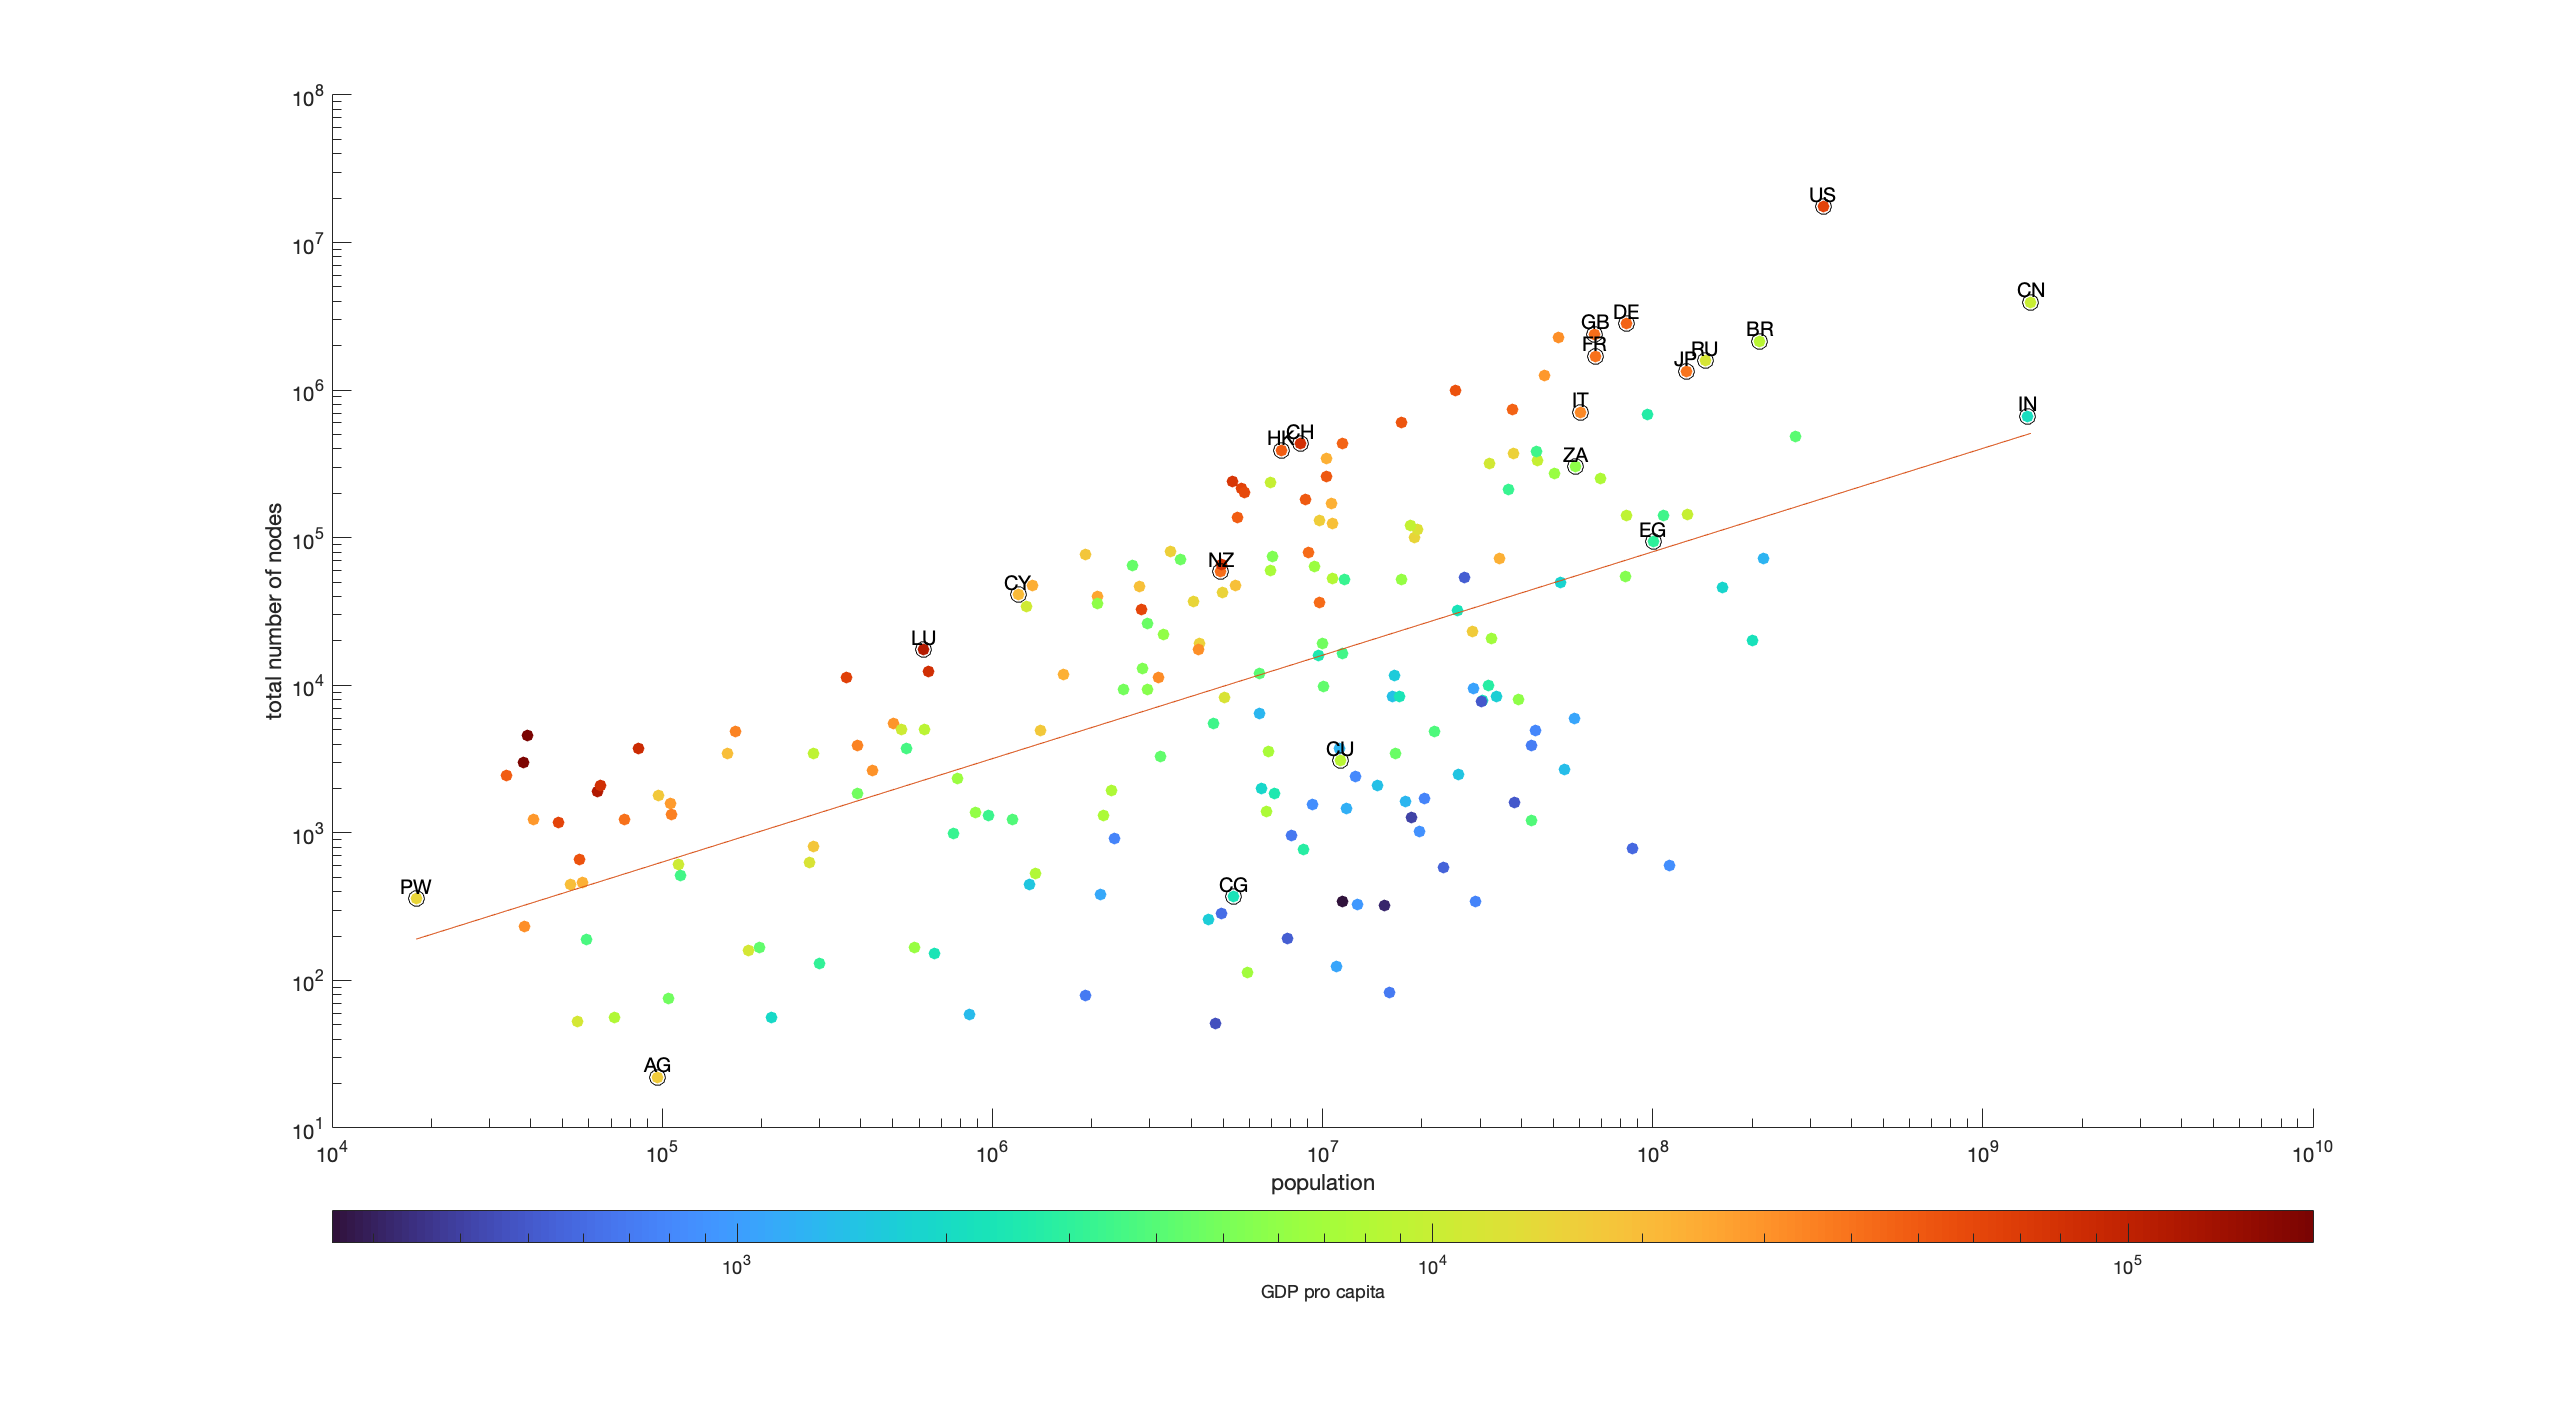

clf
% scatter plot
figure('Position', [10 10 1920 1068])
pop = lcc_pop_gdp_country.population;
tot_nodes = lcc_pop_gdp_country.count .* lcc_pop_gdp_country.largest_cc_size;
gdp = lcc_pop_gdp_country.gdp ./ lcc_pop_gdp_country.population;
scatter(pop, tot_nodes, [], gdp, "filled")
set(gca, 'YScale', 'log', 'XScale', 'log', 'ColorScale','log')
colormap turbo
c = colorbar('southoutside');
c.Label.String = "GDP pro capita";
xlabel("population")
ylabel("total number of nodes")

% highlight specific countries
countries = ['BR' "CN" "DE" "FR" "IN" "IT" "JP" "RU" "US" "CG" "CH" "CU" "CY" "EG" "GB" "NZ" "ZA" "HK" "LU" "AG" "PW"];
hold on
for i = 1:length(countries)
    country = countries(i);
    T = lcc_pop_gdp_country(country,:);
    plot(T.population, T.count * T.largest_cc_size, "Marker","o", "MarkerSize", 8, "Color", "black")
    text(T.population, T.count * T.largest_cc_size, country,'VerticalAlignment','bottom','HorizontalAlignment','center', "Color","black", "FontSize",10)
end

% regression line
X=log10(pop); Y=log10(tot_nodes);  % convert both variables to log's
b=polyfit(X,Y,1);        % estimate coefficients
[x1,i1] = min(X);       % find endpoints
[x2,i2] = max(X);
yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
loglog([pop(i1) pop(i2)],yhat) % add fitted line
hold off

nodes number vs population colored by continent

clf
% scatter plot
figure('Position', [10 10 1920 1068])
pop = lcc_pop_gdp_country.population;
tot_nodes = lcc_pop_gdp_country.count .* lcc_pop_gdp_country.largest_cc_size;
continent = lcc_pop_gdp_country.continent;
gdp = lcc_pop_gdp_country.gdp ./ lcc_pop_gdp_country.population;
gscatter(pop, tot_nodes, continent)
set(gca, 'YScale', 'log', 'XScale', 'log')
xlabel("population")

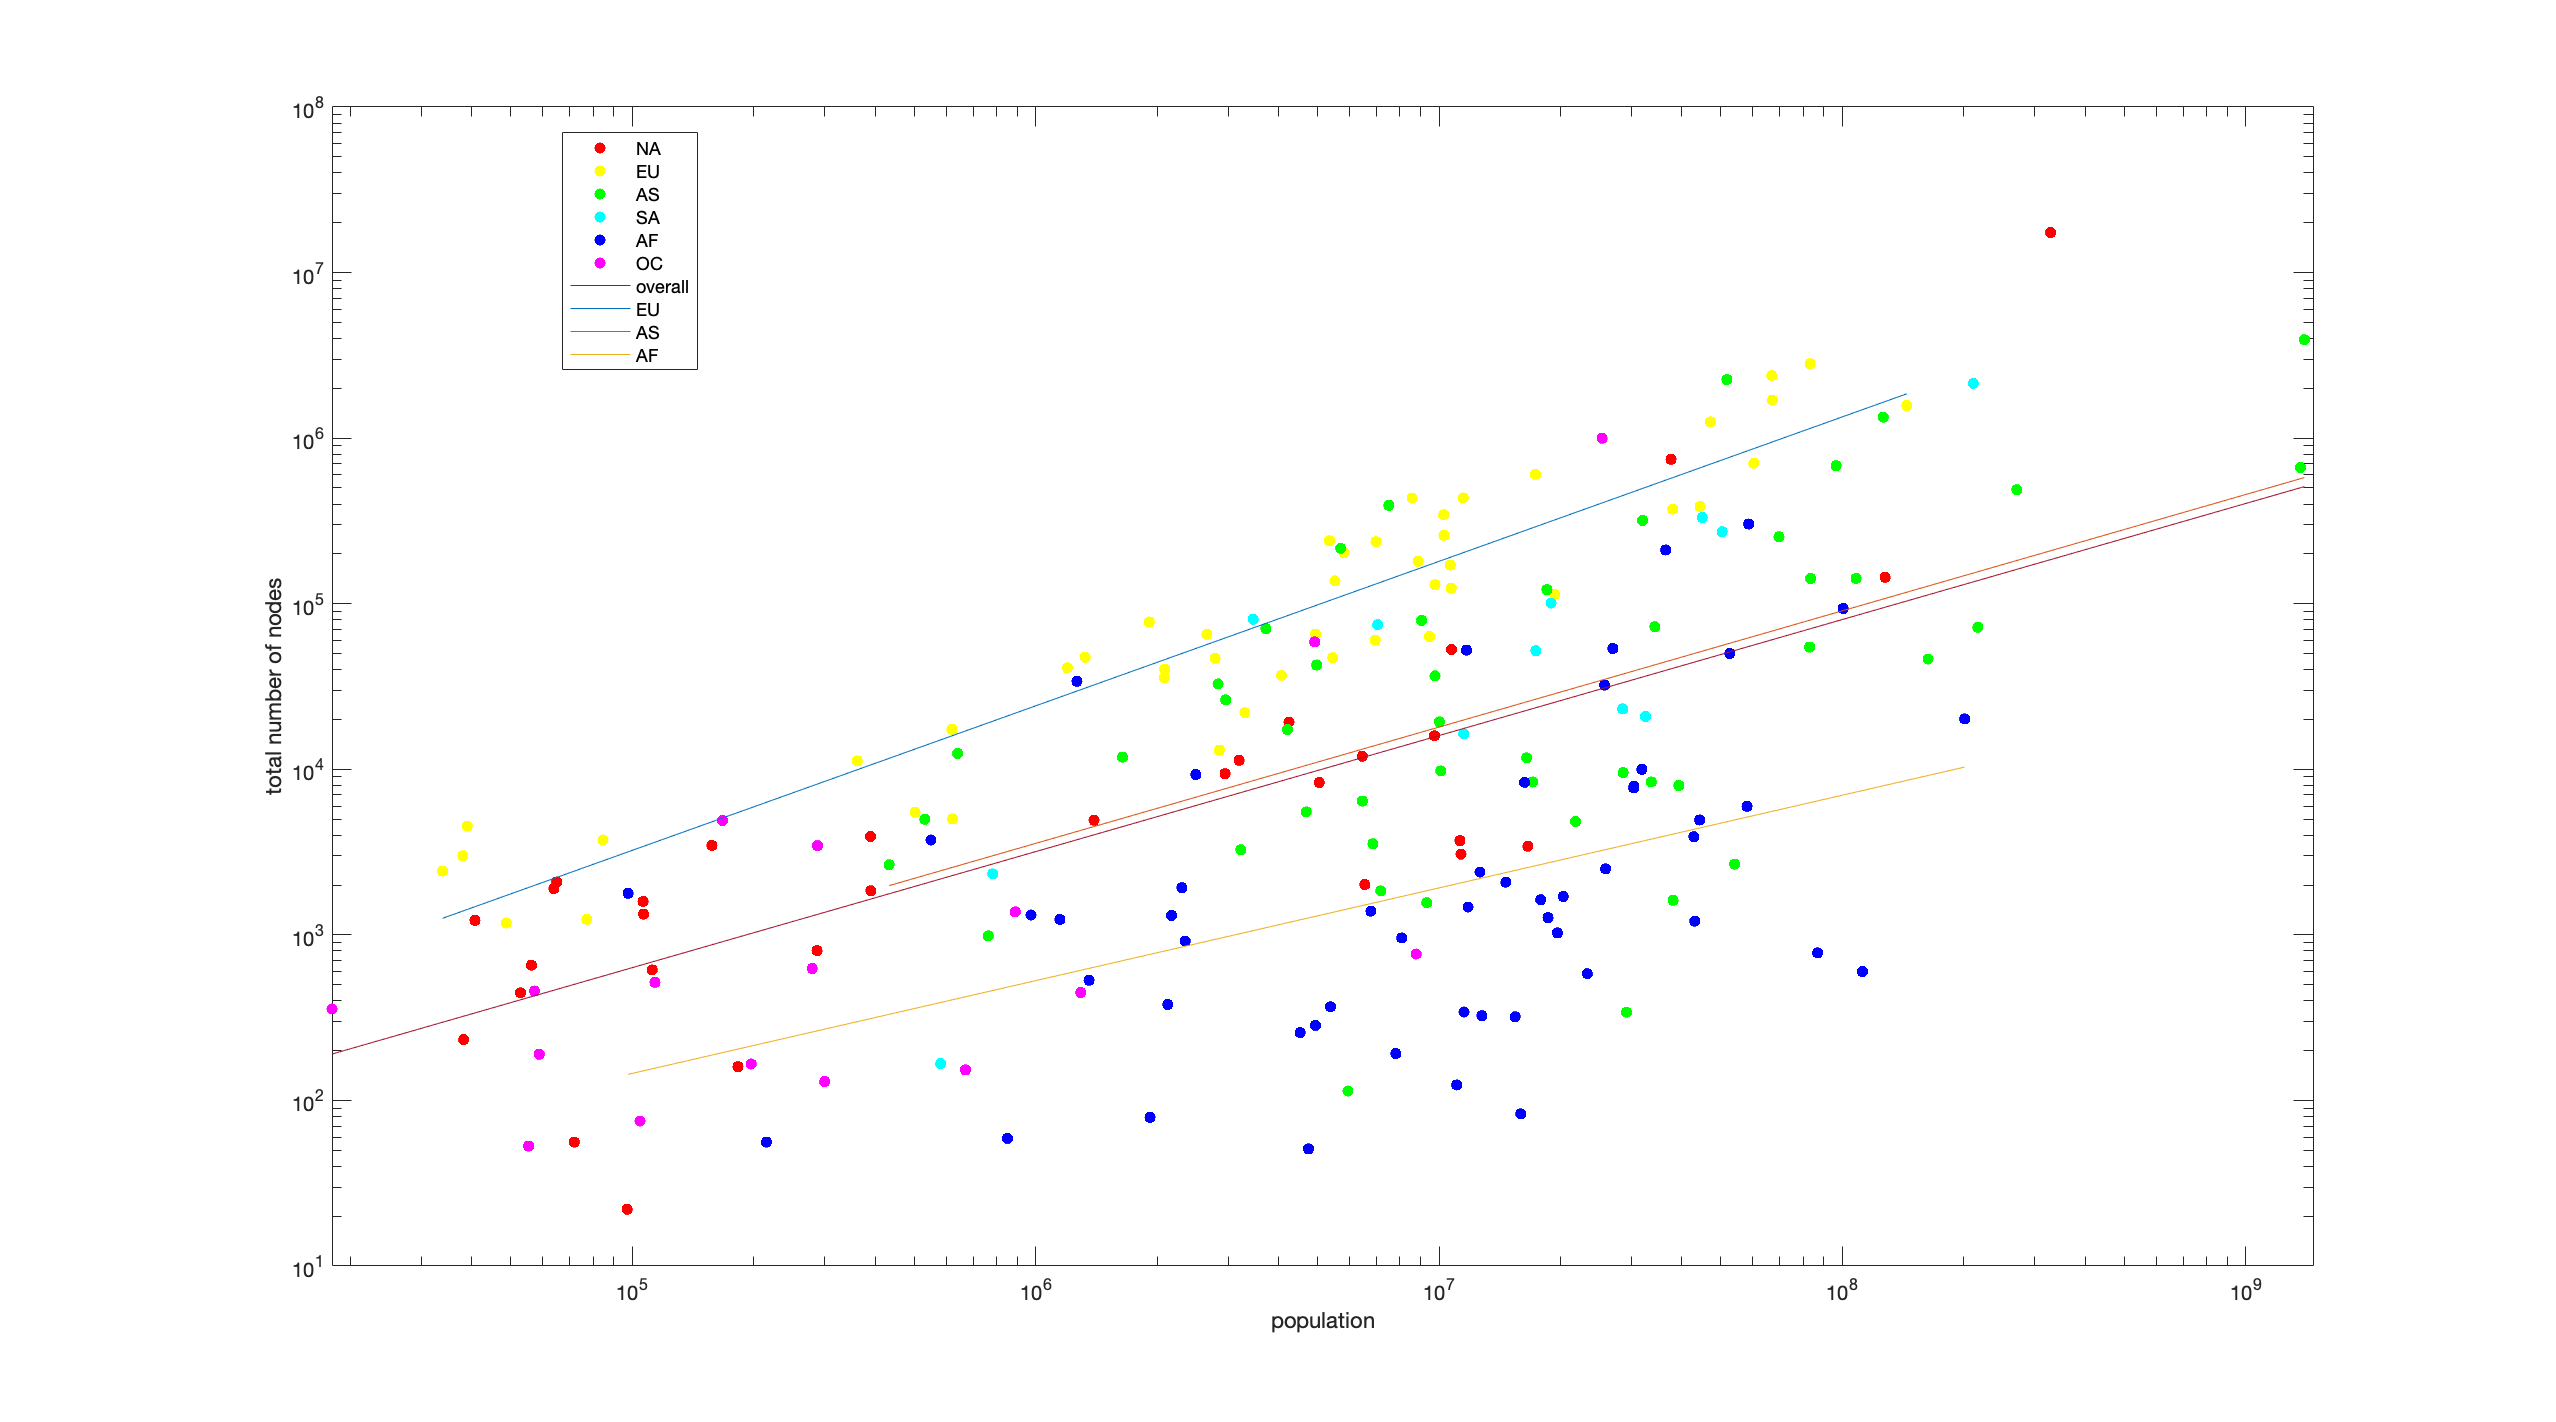

ylabel("total number of nodes")

hold on

% overall regression line
X=log10(pop); Y=log10(tot_nodes);  % convert both variables to log's
b=polyfit(X,Y,1);        % estimate coefficients
[x1,i1] = min(X);       % find endpoints
[x2,i2] = max(X);
yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
loglog([pop(i1) pop(i2)],yhat, "DisplayName", "overall") % add fitted line

% choose a list of continents of which you show the regression
continents = ["EU" "AS" "AF"];
for i = 1:length(continents)
    continent = continents(i);
    pop = lcc_pop_gdp_country.population(lcc_pop_gdp_country.continent == continent);
    tot_nodes = lcc_pop_gdp_country.count(lcc_pop_gdp_country.continent == continent) .* lcc_pop_gdp_country.largest_cc_size(lcc_pop_gdp_country.continent == continent);
    % do regression
    X=log10(pop); Y=log10(tot_nodes);  % convert both variables to log's
    b=polyfit(X,Y,1);        % estimate coefficients
    [x1,i1] = min(X);       % find endpoints
    [x2,i2] = max(X);
    yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
    loglog([pop(i1) pop(i2)],yhat, "DisplayName", continent) % add fitted line
end

hold off

number of different ASs vs total number of nodes colored by GDP

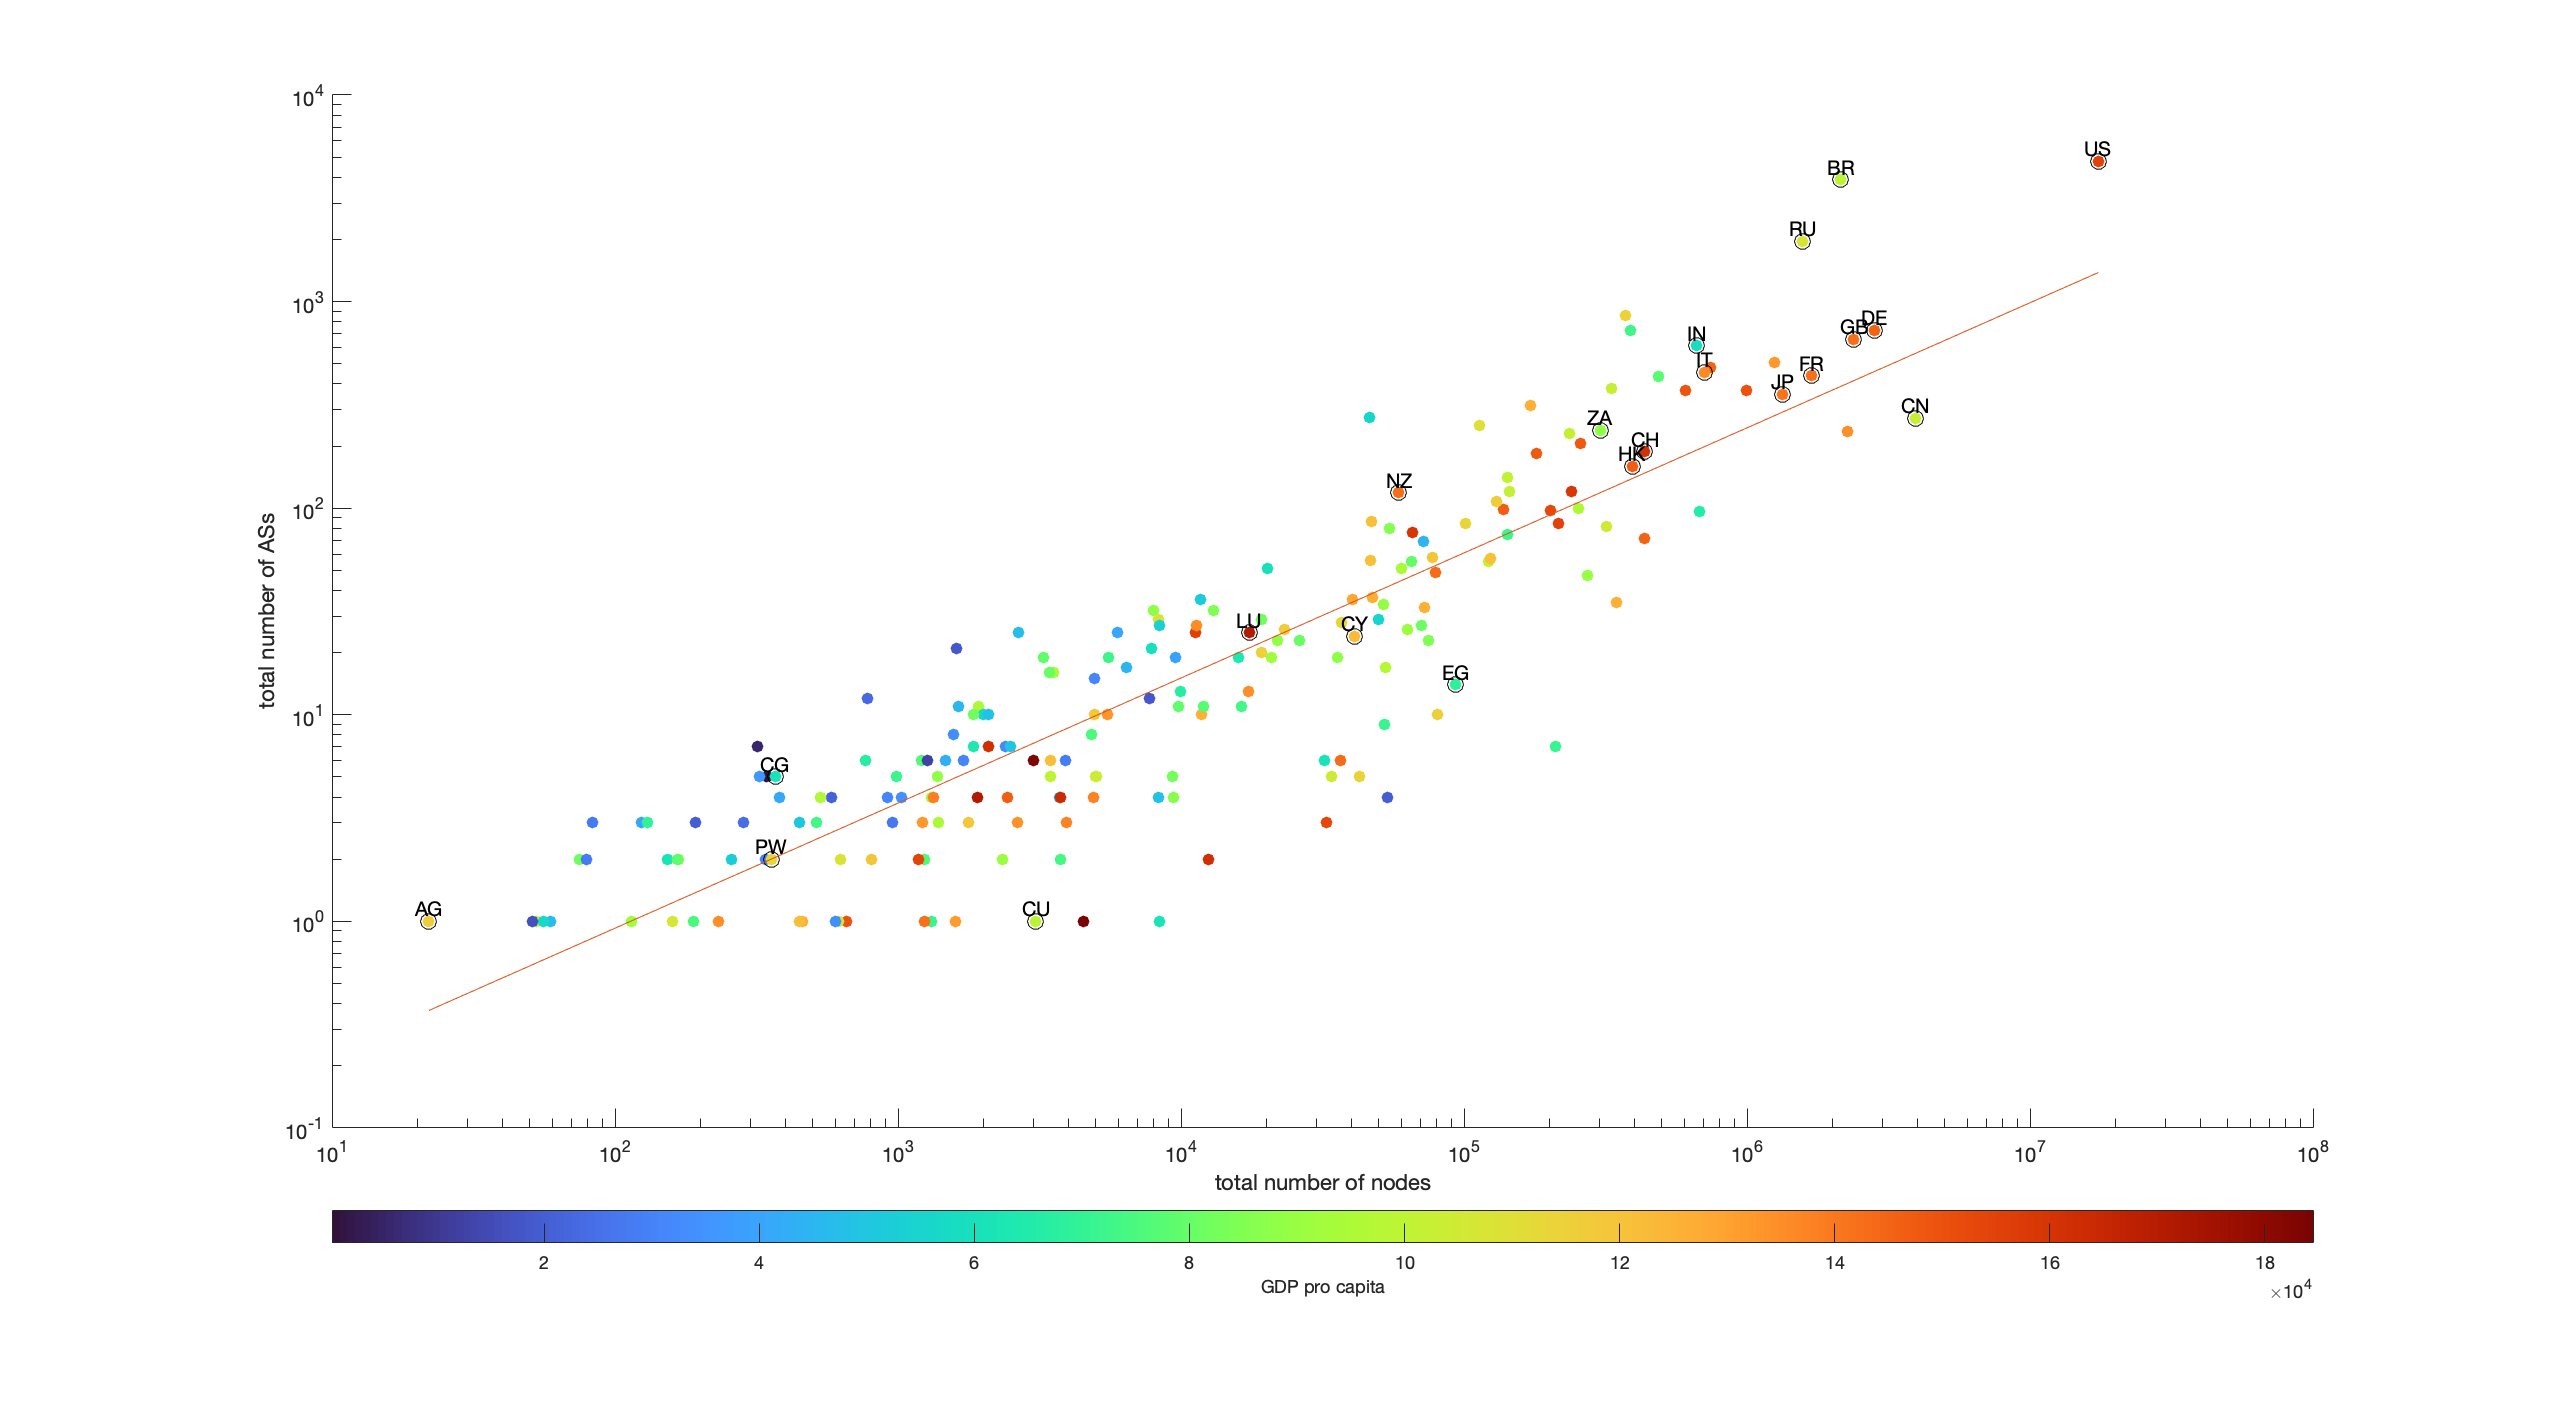

clf
% scatter plot
figure('Position', [10 10 1920 1068])
as_count = lcc_pop_gdp_country.count;
tot_nodes = lcc_pop_gdp_country.count .* lcc_pop_gdp_country.largest_cc_size;
gdp = lcc_pop_gdp_country.gdp ./ lcc_pop_gdp_country.population;
scatter(tot_nodes, as_count, [], gdp, "filled")
set(gca, 'YScale', 'log', 'XScale', 'log', 'ColorScale','log')
colormap turbo
c = colorbar('southoutside');
c.Label.String = "GDP pro capita";
xlabel("total number of nodes")
ylabel("total number of ASs")

% highlight specific countries
countries = ['BR' "CN" "DE" "FR" "IN" "IT" "JP" "RU" "US" "CG" "CH" "CU" "CY" "EG" "GB" "NZ" "ZA" "HK" "LU" "AG" "PW"];
hold on
for i = 1:length(countries)
    country = countries(i);
    T = lcc_pop_gdp_country(country,:);
    plot(T.count * T.largest_cc_size, T.count, "Marker","o", "MarkerSize", 8, "Color", "black")
    text(T.count * T.largest_cc_size, T.count, country,'VerticalAlignment','bottom','HorizontalAlignment','center', "Color","black", "FontSize",10)
end

% regression line
X=log10(tot_nodes); Y=log10(as_count);  % convert both variables to log's
b=polyfit(X,Y,1);        % estimate coefficients
[x1,i1] = min(X);       % find endpoints
[x2,i2] = max(X);
yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
loglog([tot_nodes(i1) tot_nodes(i2)],yhat) % add fitted line
hold off

number of different ASs vs total number of nodes colored by continent

clf
% scatter plot
figure('Position', [10 10 1920 1068])
as_count = lcc_pop_gdp_country.count;
tot_nodes = lcc_pop_gdp_country.count .* lcc_pop_gdp_country.largest_cc_size;
continent = lcc_pop_gdp_country.continent;
gdp = lcc_pop_gdp_country.gdp ./ lcc_pop_gdp_country.population;
gscatter(tot_nodes, as_count, continent)
set(gca, 'YScale', 'log', 'XScale', 'log')
xlabel("total number of nodes")

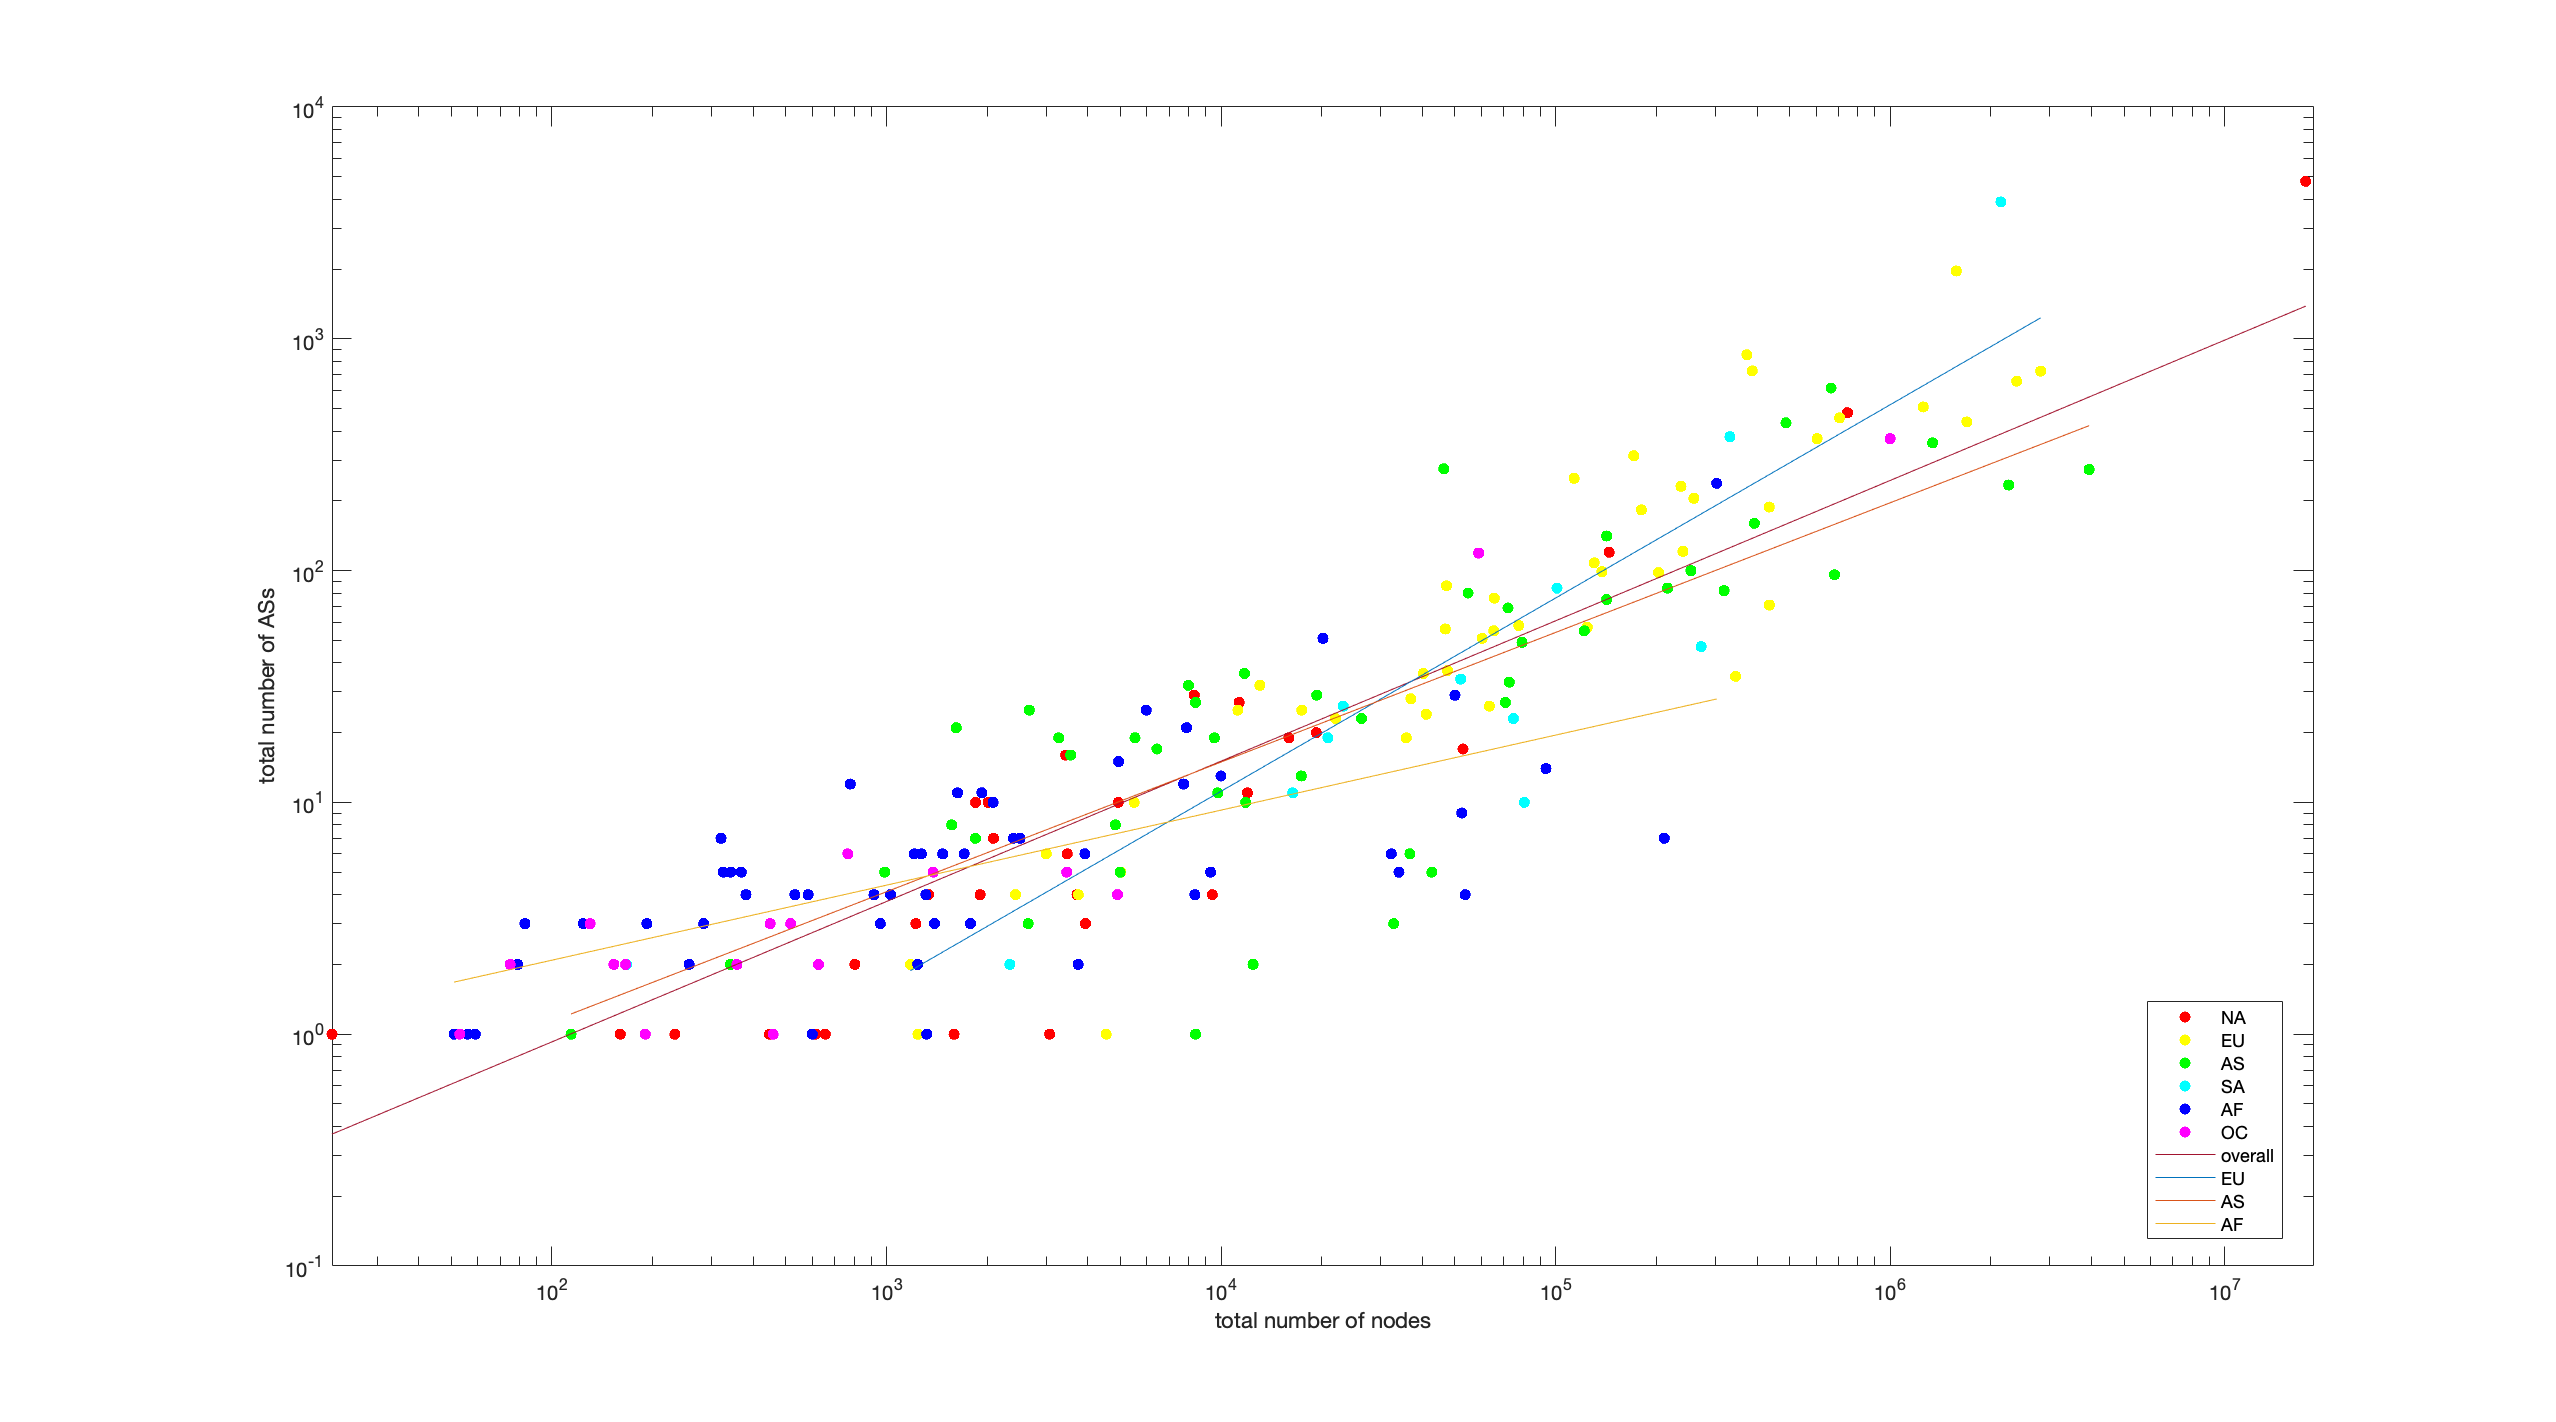

ylabel("total number of ASs")

hold on

% regression line
X=log10(tot_nodes); Y=log10(as_count);  % convert both variables to log's
b=polyfit(X,Y,1);        % estimate coefficients
[x1,i1] = min(X);       % find endpoints
[x2,i2] = max(X);
yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
loglog([tot_nodes(i1) tot_nodes(i2)],yhat, "DisplayName", "overall") % add fitted line

% choose a list of continents of which you show the regression
continents = ["EU" "AS" "AF"];
for i = 1:length(continents)
    continent = continents(i);
    as_count = lcc_pop_gdp_country.count(lcc_pop_gdp_country.continent == continent);
    tot_nodes = lcc_pop_gdp_country.count(lcc_pop_gdp_country.continent == continent) .* lcc_pop_gdp_country.largest_cc_size(lcc_pop_gdp_country.continent == continent);
    % do regression
    X=log10(tot_nodes); Y=log10(as_count);  % convert both variables to log's
    b=polyfit(X,Y,1);        % estimate coefficients
    [x1,i1] = min(X);       % find endpoints
    [x2,i2] = max(X);
    yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
    loglog([tot_nodes(i1) tot_nodes(i2)],yhat, "DisplayName", continent) % add fitted line
end

hold off

add column to table with GDP category

% add GDP pro capita column
gdp_pc = lcc_pop_gdp_country.gdp ./ lcc_pop_gdp_country.population;
lcc_pop_gdp_country.gdp_pc = gdp_pc;
table_sorted = sortrows(lcc_pop_gdp_country, "gdp_pc");

table_sorted = 206×9 table
          ds_nodes    largest_cc_size    largest_cc_coverage    count    population       gdp        continent       gdp_cat       gdp_pc
          ________    _______________    ___________________    _____    __________    __________    _________    _____________    ______

    BI       45.2           68.4               0.95244            5      1.1531e+07    3.0123e+09     {'AF'}      "medium high"    261.25
    SO     31.571         45.714               0.75714            7      1.5443e+07    4.9423e+09     {'AF'}      "high"           320.04
    MW     152.83         211.83               0.69823         


% number of categories
CATEGORY_NUM = 5;
% categories labels
category_labels = ["low" "medium low" "medium" "medium high" "high"];
% populate new column
new_col = strings(height(table_sorted),1);
% gdp values array
gdp_pc_sorted = table_sorted.gdp_pc;
category = 1;
step = ceil(length(new_col) / CATEGORY_NUM);

step = 42

for i = 1:length(new_col)
    if mod(i, step) == 0
        category = category + 1;
    end
    new_col(i) = category_labels(category);
end
table_sorted.gdp_cat = new_col;

table_sorted = 206×9 table
          ds_nodes    largest_cc_size    largest_cc_coverage    count    population       gdp        continent    gdp_cat    gdp_pc
          ________    _______________    ___________________    _____    __________    __________    _________    _______    ______

    BI       45.2           68.4               0.95244            5      1.1531e+07    3.0123e+09     {'AF'}       "low"     261.25
    SO     31.571         45.714               0.75714            7      1.5443e+07    4.9423e+09     {'AF'}       "low"     320.04
    MW     152.83         211.83               0.69823            6      1.8629e+07    

nodes number vs population colored by GDP category

clf
% scatter plot
figure('Position', [10 10 1920 1068])
pop = table_sorted.population;
tot_nodes = table_sorted.count .* table_sorted.largest_cc_size;
gdp_cat = table_sorted.gdp_cat;
gscatter(pop, tot_nodes, gdp_cat)
set(gca, 'YScale', 'log', 'XScale', 'log')
xlabel("population")

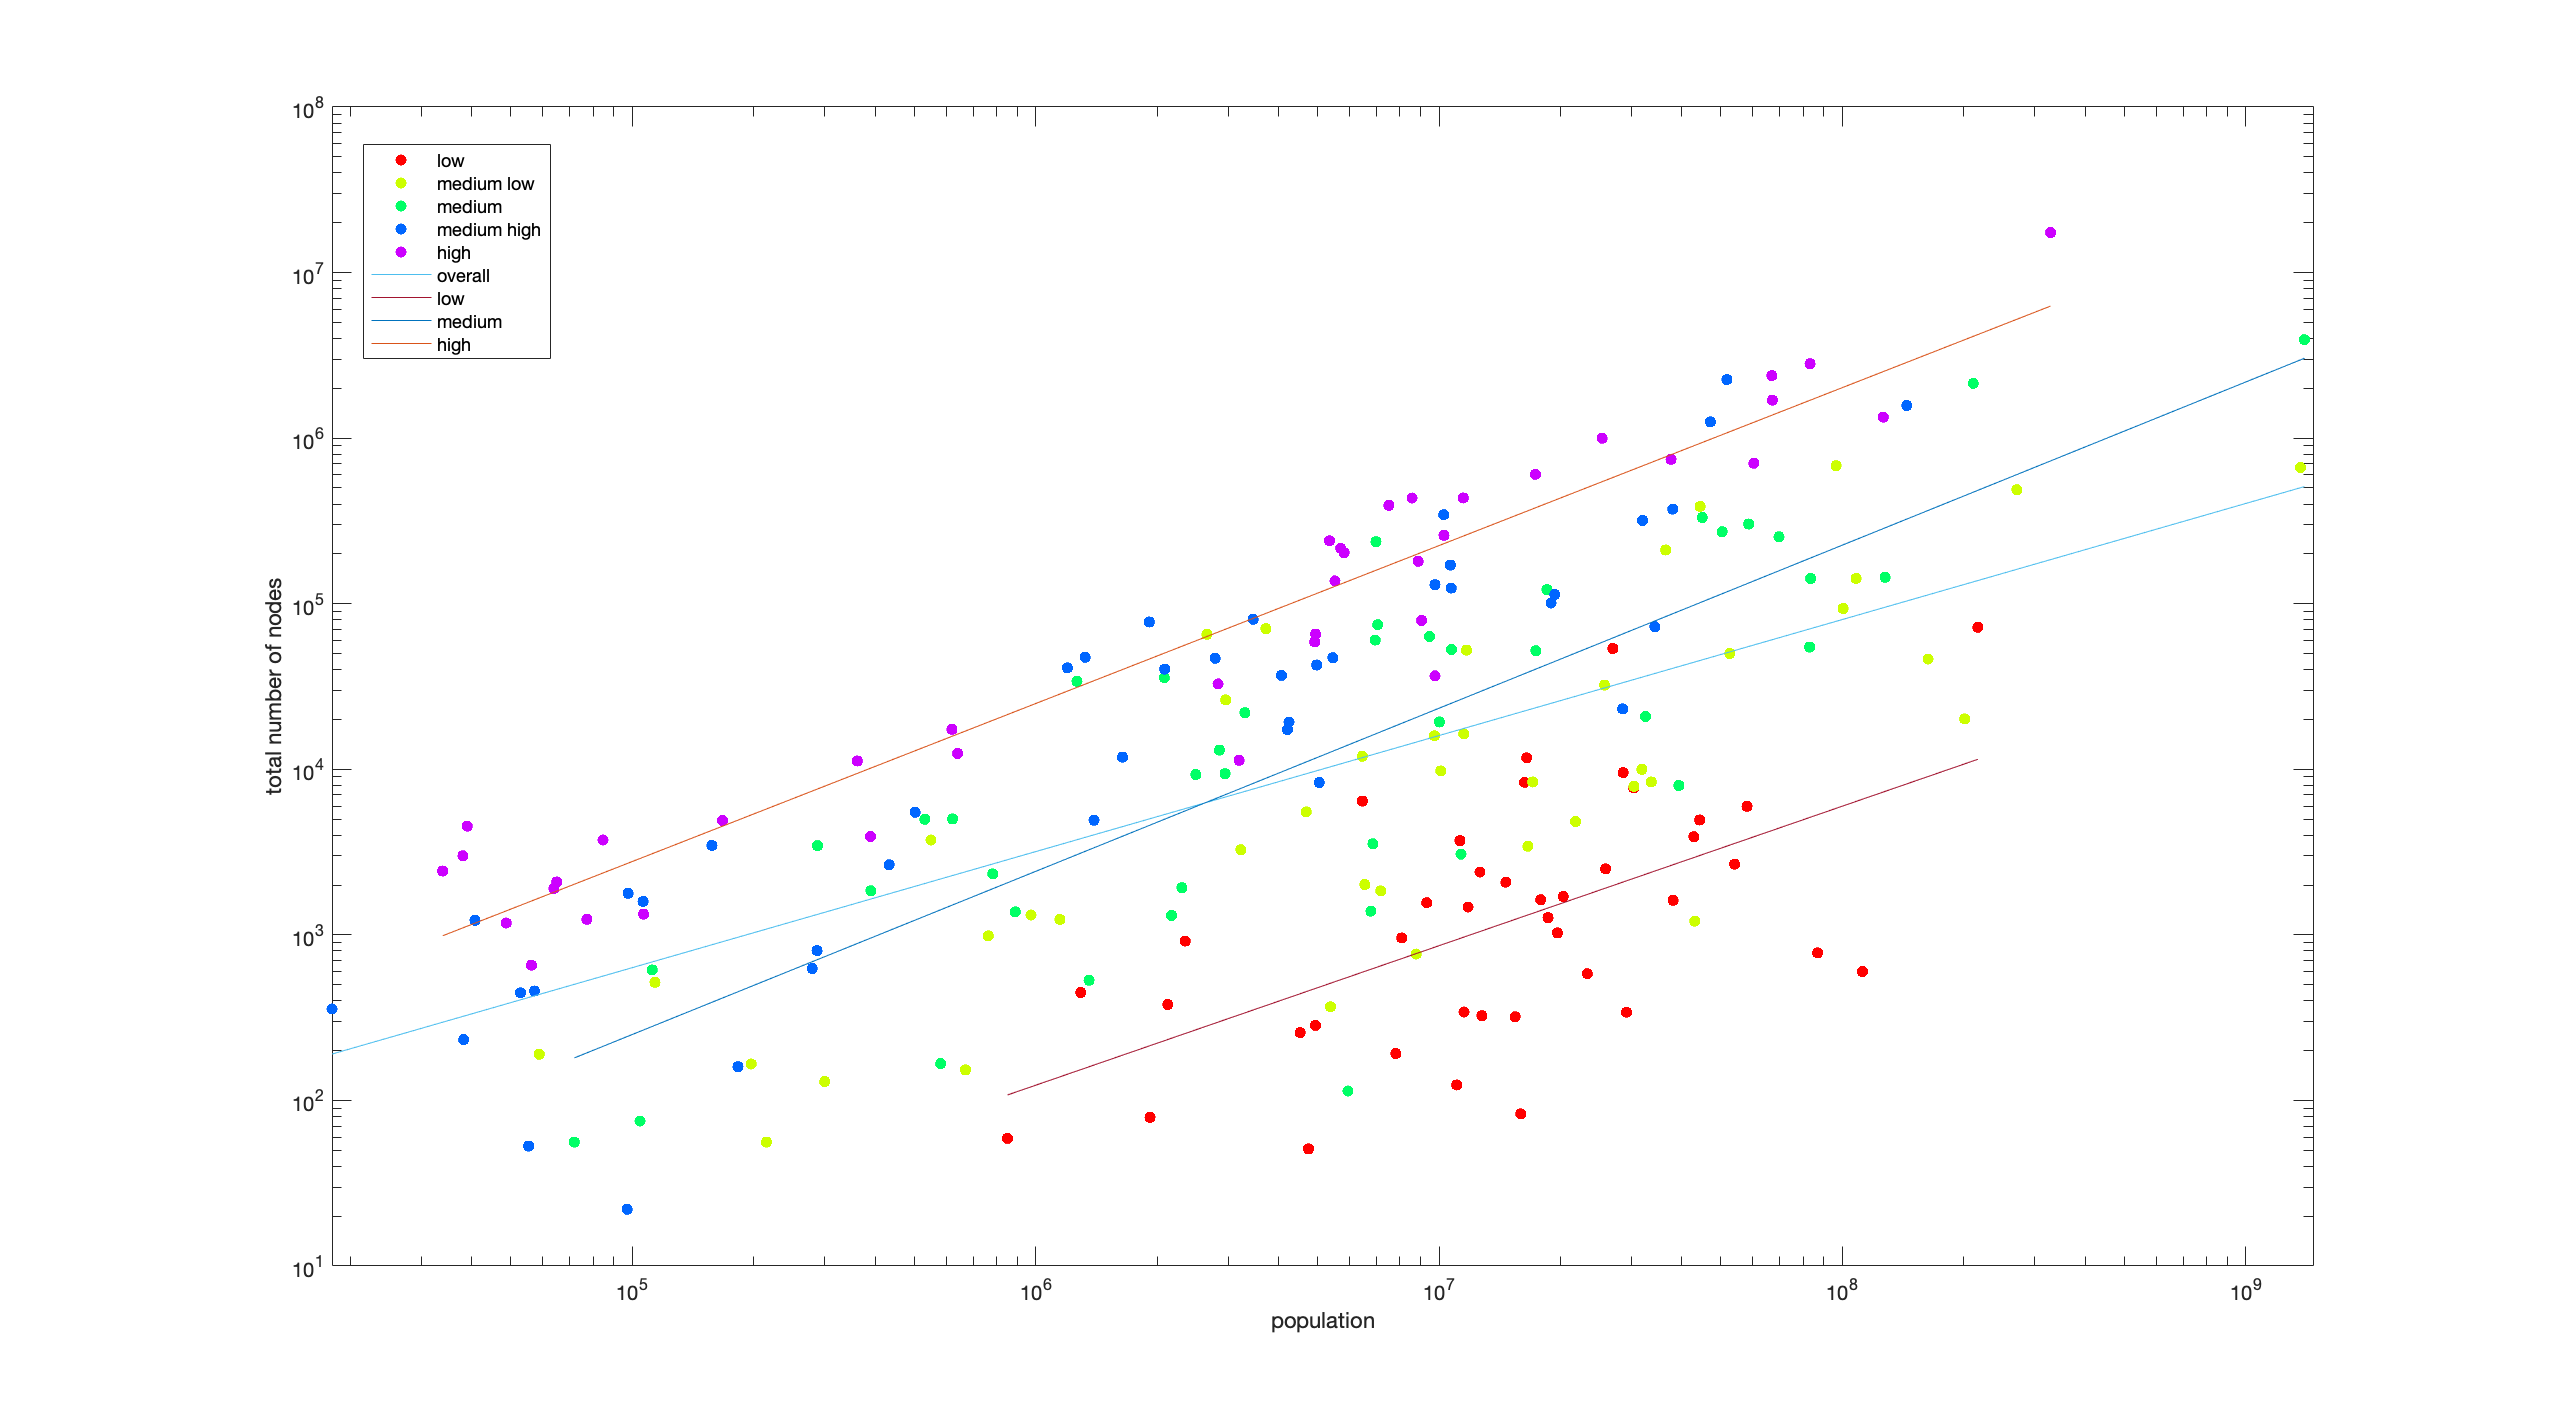

ylabel("total number of nodes")

hold on

% overall regression line
X=log10(pop); Y=log10(tot_nodes);  % convert both variables to log's
b=polyfit(X,Y,1);        % estimate coefficients
[x1,i1] = min(X);       % find endpoints
[x2,i2] = max(X);
yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
loglog([pop(i1) pop(i2)],yhat, "DisplayName", "overall") % add fitted line

% choose a list of continents of which you show the regression
gdp_cats = ["low" "medium" "high"];
for i = 1:length(gdp_cats)
    gdp_cat = gdp_cats(i);
    pop = table_sorted.population(table_sorted.gdp_cat == gdp_cat);
    tot_nodes = table_sorted.count(table_sorted.gdp_cat == gdp_cat) .* table_sorted.largest_cc_size(table_sorted.gdp_cat == gdp_cat);
    % do regression
    X=log10(pop); Y=log10(tot_nodes);  % convert both variables to log's
    b=polyfit(X,Y,1);        % estimate coefficients
    [x1,i1] = min(X);       % find endpoints
    [x2,i2] = max(X);
    yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
    loglog([pop(i1) pop(i2)],yhat, "DisplayName", gdp_cat) % add fitted line
end

hold off

LCC coverage vs GDP pro capita colored by continent

clf
% scatter plot
% figure('Position', [10 10 1920 1068])
lcc_cov = table_sorted.largest_cc_coverage;
gdp_pc = table_sorted.gdp_pc;
continent = table_sorted.continent;
gscatter(gdp_pc, lcc_cov, continent)
set(gca, 'XScale', 'log')
xlabel("GDP pro capita")

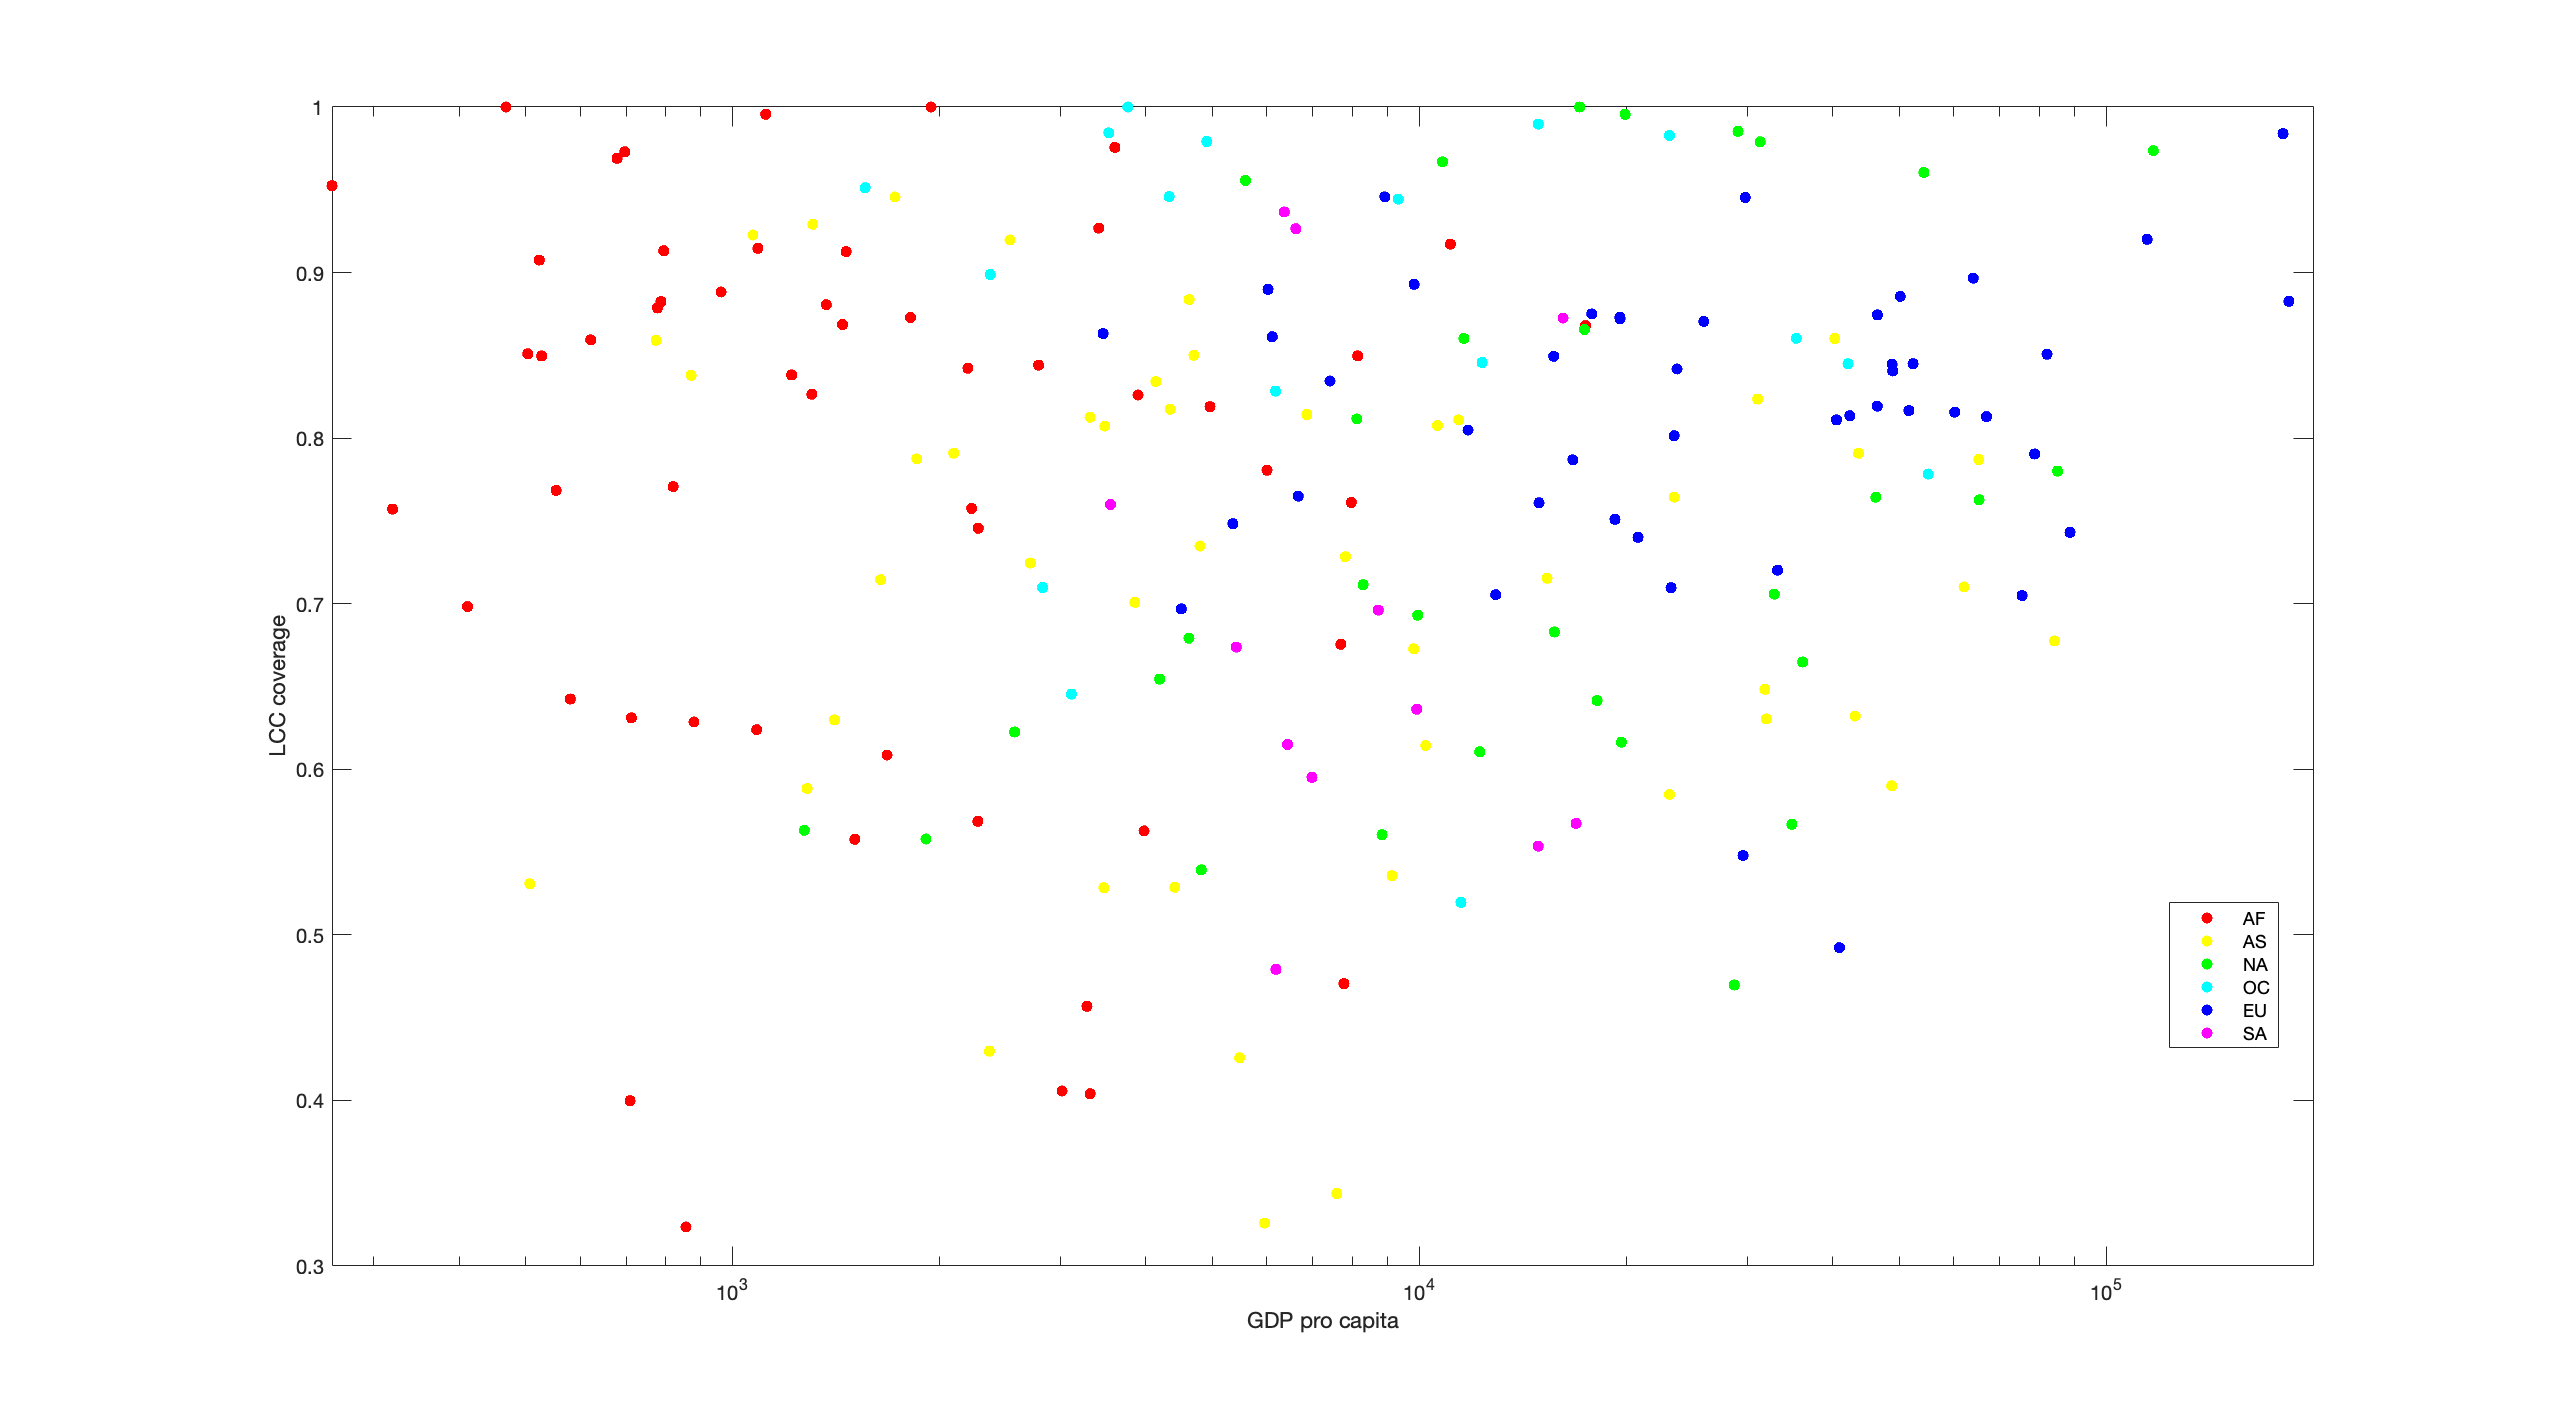

ylabel("LCC coverage")